# MCMMP

rangeLow = -pi;
rangeHigh = pi;
xInit = linspace(rangeLow, rangeHigh, 200);
m = 10;
fun = @(x) x + sin(x .^ 2);

## Noduri echidistante

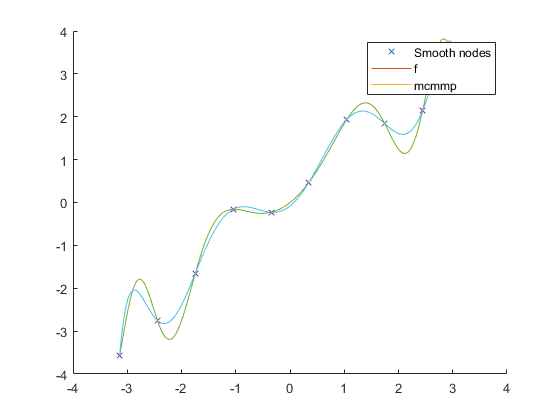

x = linspace(rangeLow, rangeHigh, m);
y = fun(x);

ySmooth = cmmp(x,y, xInit);

figure(1);
hold on;
plot(x, y, 'x');
plot(xInit, fun(xInit));
plot(xInit, ySmooth);
legend('Smooth nodes', 'f', 'mcmmp')